fname = 'Fig1h_kymo_all_tracks_global_ringtype_iMedFilt_VerCINI data.csv';
data= importdata(fname);

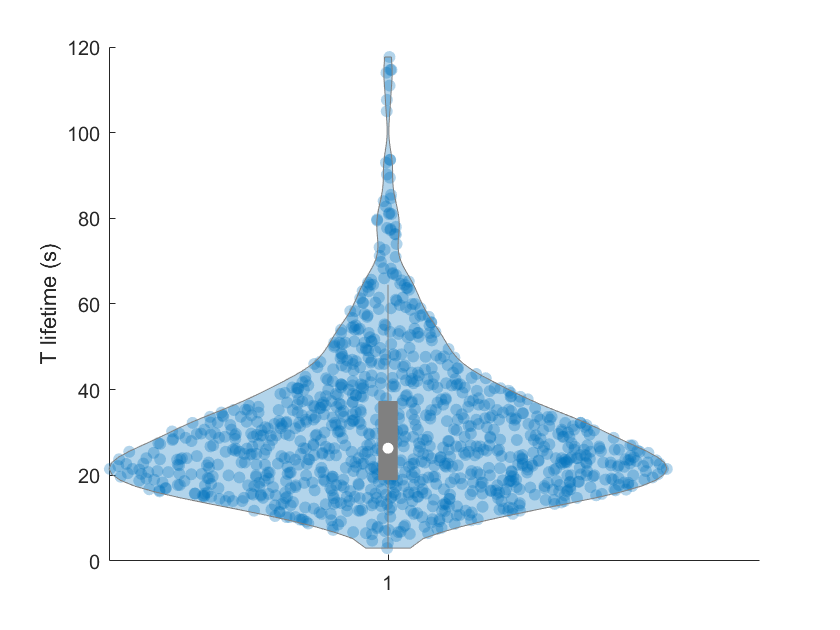

T=abs(data.data(:,2));
S=abs(data.data(:,3));
Diam=data.data(:,7);
isNascent=logical(data.data(:,8));

%keep only the nascent population
T=T(isNascent);%nascent
S=S(isNascent);
Diam=Diam(isNascent);

figure;
violinplot(T);
ylabel('T lifetime (s)');

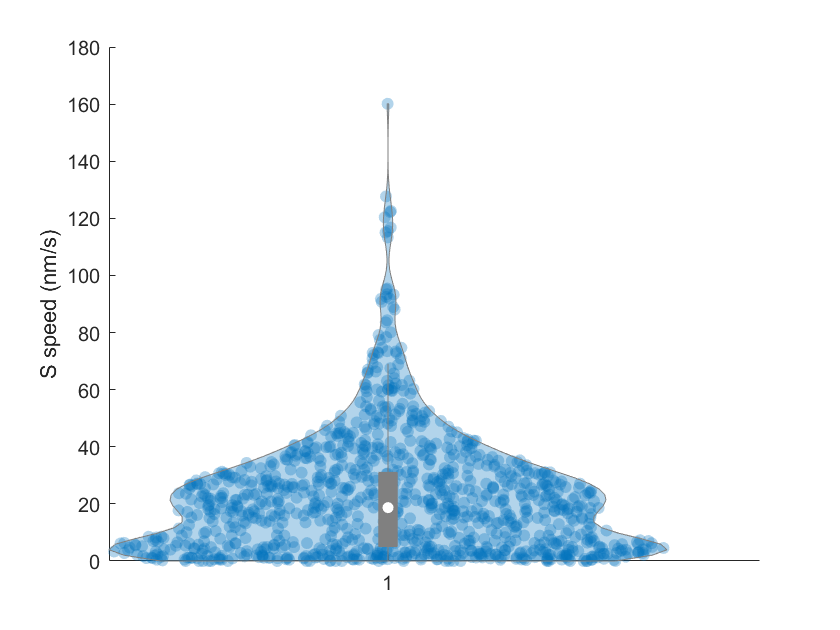


figure;
violinplot(S);
ylabel('S speed (nm/s)')

nascentTracks=table;
nascentTracks.T=T;
nascentTracks.S=S;
nascentTracks.Diam=Diam;
save("nascentTrackData.mat","T","S","Diam","nascentTracks");

nTrackData=numel(T);
TSmat = [T,S];
nTrackKymoAvg=10;
nId=poissrnd(nTrackKymoAvg)

nId = 11

bootId=randi(nTrackData,nId,1)

bootId =          862
         358
         244
         877
         372
         177
          30
        1019
         726
         918


trackBootstrapped=TSmat(bootId,:)

trackBootstrapped =    14.7500   24.2373
   23.5000   18.6702
   34.6667   20.6250
    8.3333  122.2000
   22.5000   52.0000
   15.7500   38.1746
   33.5000    7.7612
   89.5000   23.9665
   54.2500    5.9908
   20.7500   23.4940


Above code outlines approach for resampling of the real data to generate ground truth for artificial kymographs

Now test the simulator implementation

nTrackKymoAvg=10;
trackBootstrapped=genSimTrackTS(nascentTracks,nTrackKymoAvg)

bootId =    181
   567
   676
    16
   502
   945
   122
   472
   704
   315


trackBootstrapped = 11×3 table
      T         S        Diam 
    ______    ______    ______

      14.5    51.552    986.23
    30.333    17.857    891.72
    23.833    15.909    935.87
      42.5    14.912     853.9
      15.5    25.161    847.25
        26      3.75    801.06
     14.25    1.1404    951.76
        14    40.238    936.63
     11.75    95.425    921.71
        13    53.333    853.17
     41.25    17.727    945.97


%save('exemplarKymoTrack_single.mat','trackBootstrapped');


%figure out stats on the nascent rings
T=readtable(fname);
%assign unique id to each ring
T.id=zeros(size(T.n));
id=1;
T.id(1)=1;
for ii=2:numel(T.id)
    if(T.ROI_(ii)-T.ROI_(ii-1)<0)
        id=id+1;
    end
    T.id(ii)=id;
end
Tnascent=T(T.IsNascent==1,:);
nTrack=max(Tnascent.id);
%average # of tracks:
ringStat=table;
id=unique(Tnascent.id);
n=numel(id);
for ii=1:n
    ringCur=Tnascent(Tnascent.id==id(ii),:);
    ringDiam(ii)=ringCur.DiameterNm(1);
    ringNTrack(ii)=size(ringCur,1);
end
ringStat.Diam=ringDiam;
ringStat.NTrack=ringNTrack;
median(ringStat.Diam)

ans = 878.3885

median(ringStat.NTrack)

ans = 6

mean(ringStat.NTrack)

ans = 5.8251

var(ringStat.NTrack)

ans = 4.4198

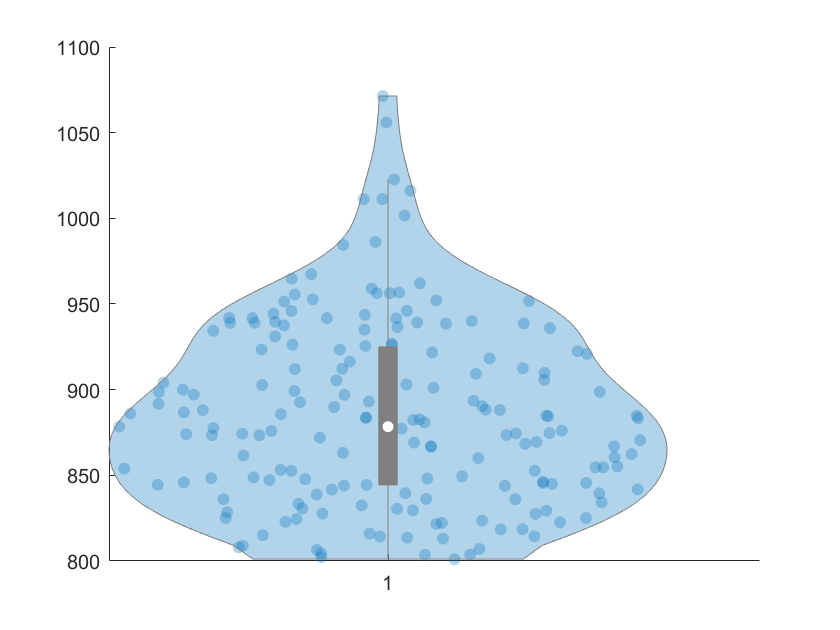

figure;
violinplot(ringStat.Diam);

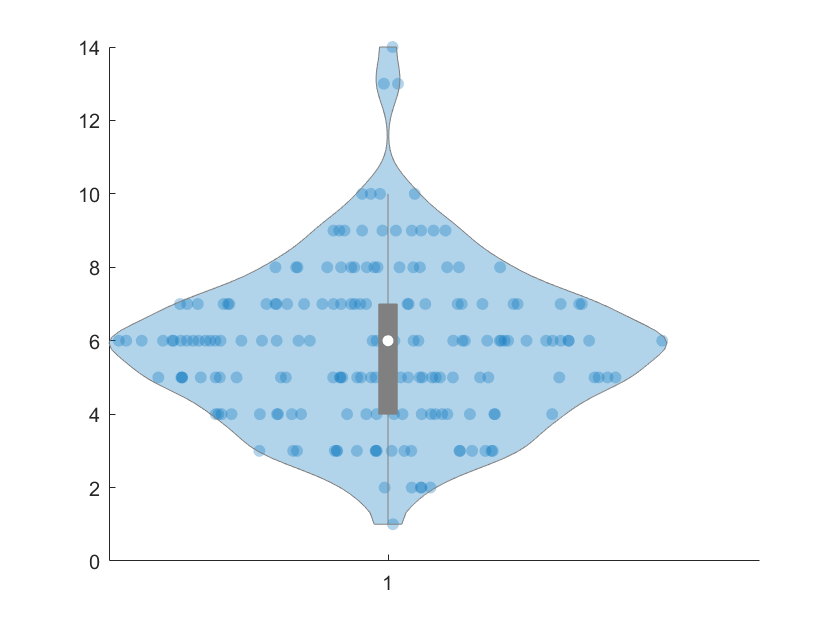

figure
violinplot(ringStat.NTrack);